# optimize event mining 

#### 1.remove M duplicate 

Events with same K and starting time were removed expect the one with highest M. 

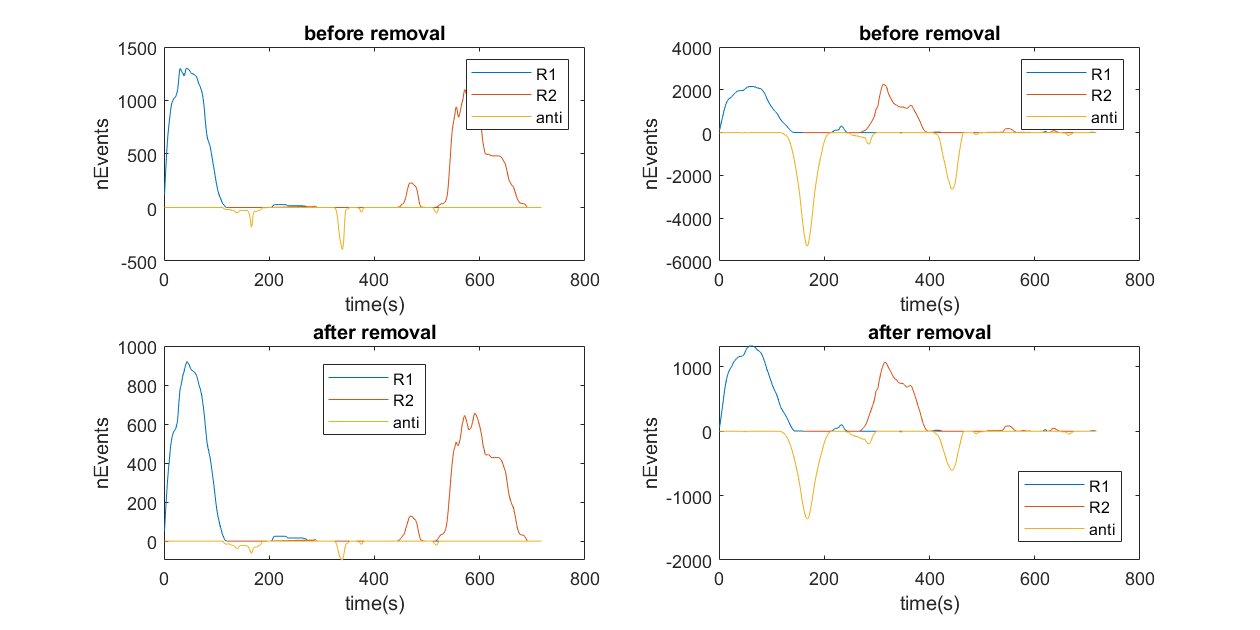

load('em_arena_th0.5.mat')
load('em_arena_antievent_0.05.mat')
close all
f=figure;f.Position(3)=1.5*f.Position(3);
for p=1
    for m = 1:2
        subplot(2,2,m)
        plot(em{1,1}.ne{p,m});xlabel('time(s)');ylabel('nEvents');title("before removal")
        hold on
        plot(find(em{2,1}.timefilter{p,m}),em{2,1}.ne{p,m});
        plot(-anti{1,1}.ne{p,m});legend({'R1','R2','anti'})
    end
    em=rem_dup_em(em);anti=rem_dup_em(anti,'nround',1);
    for m=1:2
        subplot(2,2,2+m)
        plot(em{1,1}.ne{p,m});
        hold on
        plot(find(em{2,1}.timefilter{p,m}),em{2,1}.ne{p,m});xlabel('time(s)');ylabel('nEvents');title("after removal")
        plot(-anti{1,1}.ne{p,m});legend({'R1','R2','anti'},'Location',"best")
    end
end

#### 2. limit range of k 

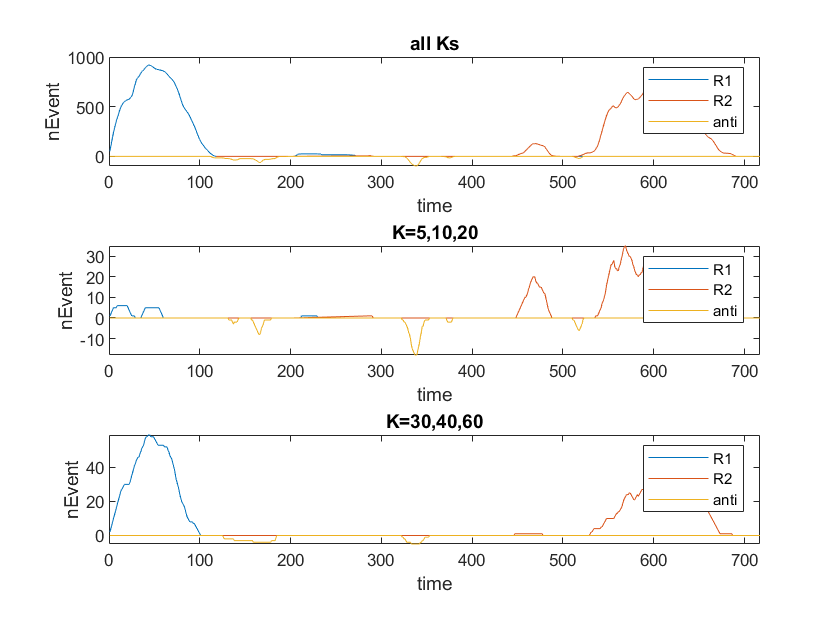

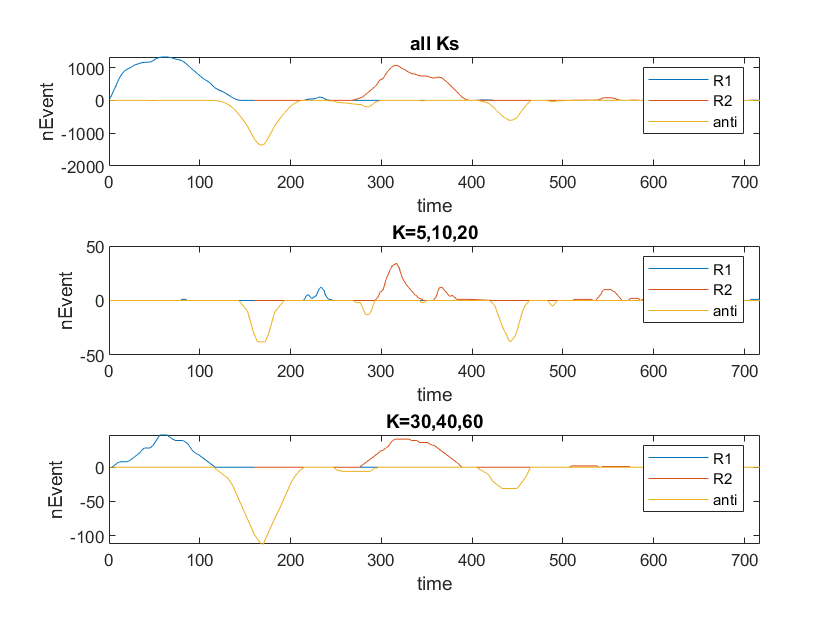

load('em_arena_th0.5.mat')
load('em_arena_antievent_0.05.mat')
em=rem_dup_em(em);
anti=rem_dup_em(anti,'nround',1);
[N,nm]=size(em{1,1}.eve);
klist{1}=[5,10,20]; % define lists of k to limit events
klist{2}=[30,40,60];
ne_klist=cell(N,nm);
% events
for l=1:2 % klist
    for r=1:2 % round
        for p=1:N
            for m=1:2
                [K,M,time]=limitk(klist{l},em{r,1}.K{p,m},em{r,1}.M{p,m},em{r,1}.time{p,m});
                if r ==1
                    s=size(em{1,1}.ca_cl{p,m},2);
                elseif r==2
                    s=sum(em{2,1}.timefilter{p,m});
                end
                [ne_klist{l}{p,m}]=count_eve(K,time,s);
            end
        end
        em{r,1}.ne_klist{l}=ne_klist{l};em{r,1}.klist=klist;
    end
end
% anti-events
for l=1:2
    for p=1:N
        for m=1:2
            [K,M,time]=limitk(klist{l},anti{1,1}.K{p,m},anti{1,1}.M{p,m},anti{1,1}.time{p,m});
            s=size(em{1,1}.ca_cl{p,m},2);
            [ne_klist{l}{p,m}]=count_eve(K,time,s);
        end
    end
end
anti{1,1}.ne_klist=ne_klist;anti{1,1}.klist=klist;
% plot
close all
for p=1
    for m=1:2
        figure
        subplot(3,1,1)
        plot(em{1,1}.ne{p,m});hold on
        plot(find(em{2,1}.timefilter{p,m}),em{2,1}.ne{p,m});title('all Ks');
        plot(-anti{1,1}.ne{p,m});xlim([0 size(em{1,1}.ca_cl{p,m},2)])
        legend({'R1','R2','anti'});xlabel('time');ylabel('nEvent');
        subplot(3,1,2)
        plot(em{1,1}.ne_klist{1}{p,m});hold on
        plot(find(em{2,1}.timefilter{p,m}),em{2,1}.ne_klist{1}{p,m});title('K=5,10,20')
        plot(-anti{1,1}.ne_klist{1}{p,m});xlim([0 size(em{1,1}.ca_cl{p,m},2)])
        legend({'R1','R2','anti'});xlabel('time');ylabel('nEvent');
        subplot(3,1,3)
        plot(em{1,1}.ne_klist{2}{p,m});hold on
        plot(find(em{2,1}.timefilter{p,m}),em{2,1}.ne_klist{2}{p,m});title('K=30,40,60')
        plot(-anti{1,1}.ne_klist{2}{p,m});xlim([0 size(em{1,1}.ca_cl{p,m},2)])
        legend({'R1','R2','anti'});xlabel('time');ylabel('nEvent');
    end
end

#### Plot M and start time as y and x axis for selected K 

load('em_arena_th0.5.mat')
load('em_arena_antievent_0.05.mat')
em=rem_dup_em(em);
anti=rem_dup_em(anti,'nround',1);
[N,nm]=size(em{1,1}.eve);
klist={5,10,20,40,60};% find events separately for each k
% events
for l=1:length(klist)
    for r=1:2
        for p=1:N
            for m=1:2
                [K,M,time]=limitk(klist{l},em{r,1}.K{p,m},em{r,1}.M{p,m},em{r,1}.time{p,m});
                allt{p,m}=[];allm{p,m}=[];
                for i = 1:length(M)
                    allt{p,m}=[allt{p,m},time{i}];
                    allm{p,m}=[allm{p,m},repelem(M(i),length(time{i}))];
                end
            end
        end
        em{r,1}.allt{l}=allt;em{r,1}.allm{l}=allm;em{r,1}.klist=klist;
    end
end
% anti-events
for l=1:length(klist)
    for p=1:N
        for m=1:2
            [K,M,time]=limitk(klist{l},anti{1,1}.K{p,m},anti{1,1}.M{p,m},anti{1,1}.time{p,m});
            allt{p,m}=[];allm{p,m}=[];
            for i = 1:length(M)
                allt{p,m}=[allt{p,m},time{i}];
                allm{p,m}=[allm{p,m},repelem(M(i),length(time{i}))];
            end
        end
    end
    anti{1,1}.allt{l}=allt;anti{1,1}.allm{l}=allm;anti{1,1}.klist=klist;
end

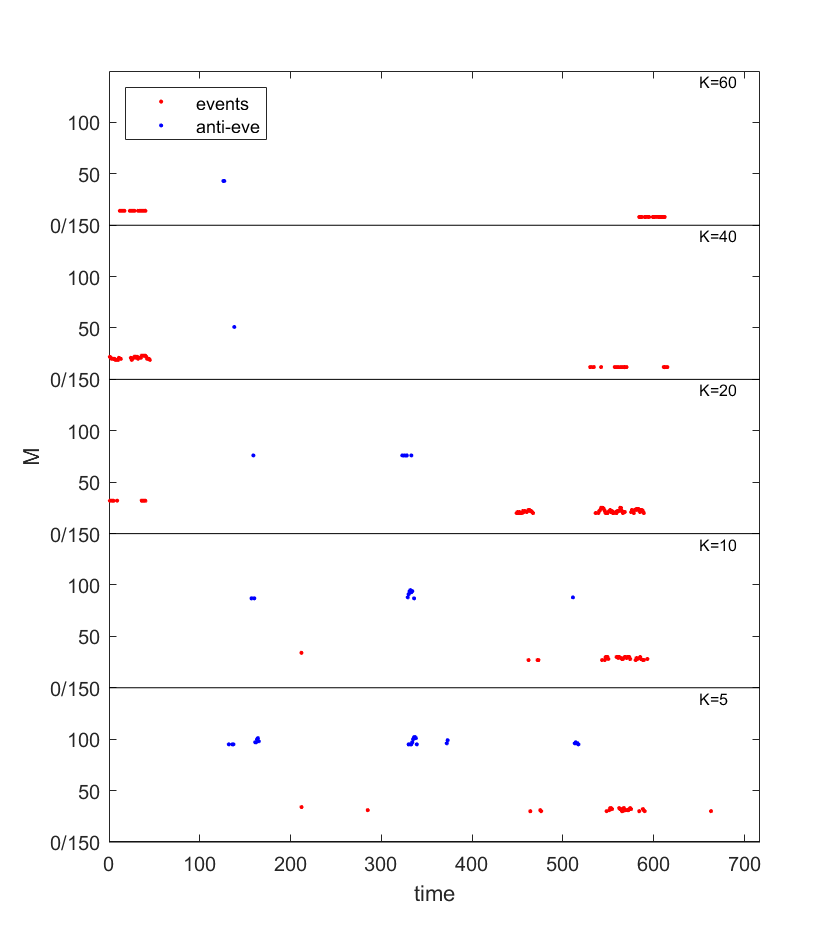

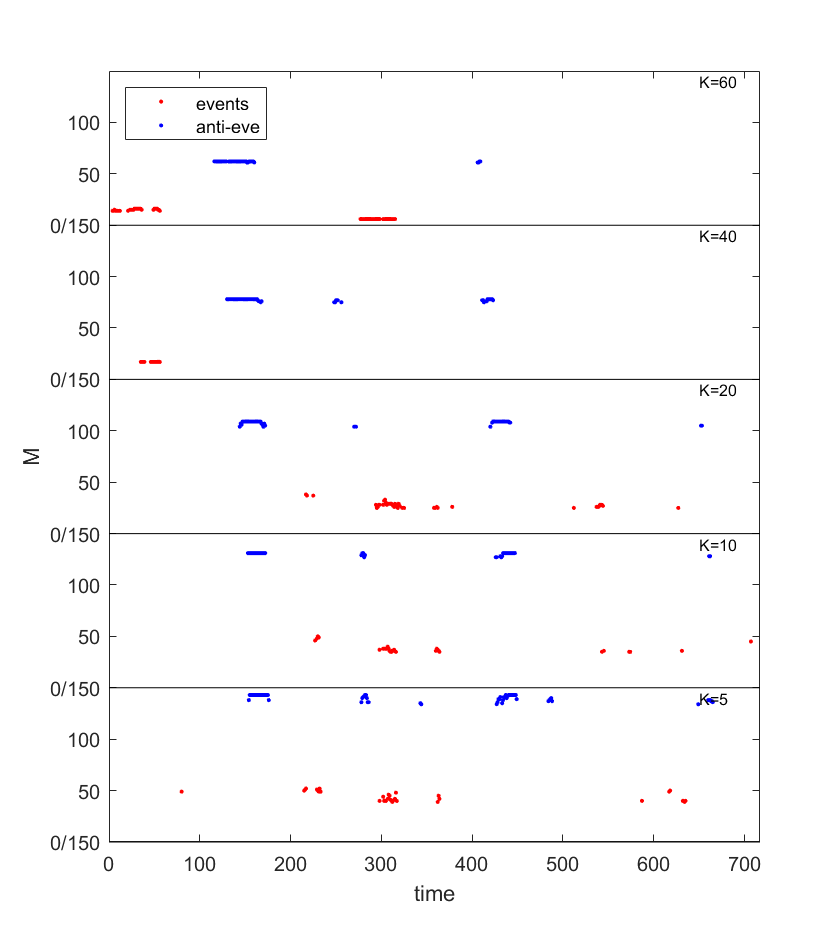

% plot
close all
for p=1
    for m=1:2
        f=figure;f.Position(4)=1.5*f.Position(4);
        for k=1:5
            p1=plot(em{1,1}.allt{k}{p,m},em{1,1}.allm{k}{p,m}+150*(k-1),'r.');
            xlabel('time');ylabel('M');
            hold on
            newt=find(em{2,1}.timefilter{p,m});
            p2=plot(newt(em{2,1}.allt{k}{p,m}),em{2,1}.allm{k}{p,m}+150*(k-1),'r.');
            %title(sprintf('K=%d',klist{k}));
            p3=plot(anti{1,1}.allt{k}{p,m},anti{1,1}.allm{k}{p,m}+150*(k-1),'b.');xlim([0 size(em{1,1}.ca_cl{p,m},2)])
            line(xlim,[150*(k-1) 150*(k-1)],'Color',[0 0 0]);text(650,150*k,sprintf('K=%d',klist{k}),'VerticalAlignment',"top",'FontSize',8)
            legend([p1 p3],{'events','anti-eve'},'Location',"northwest")
        end
        ylim([0 150*5]);yticks(0:50:5*150);yticklabels(repmat(["0/150","50","100"],1,5))
    end
end